chimp = getgenbank('NC_001643','SequenceOnly',true);

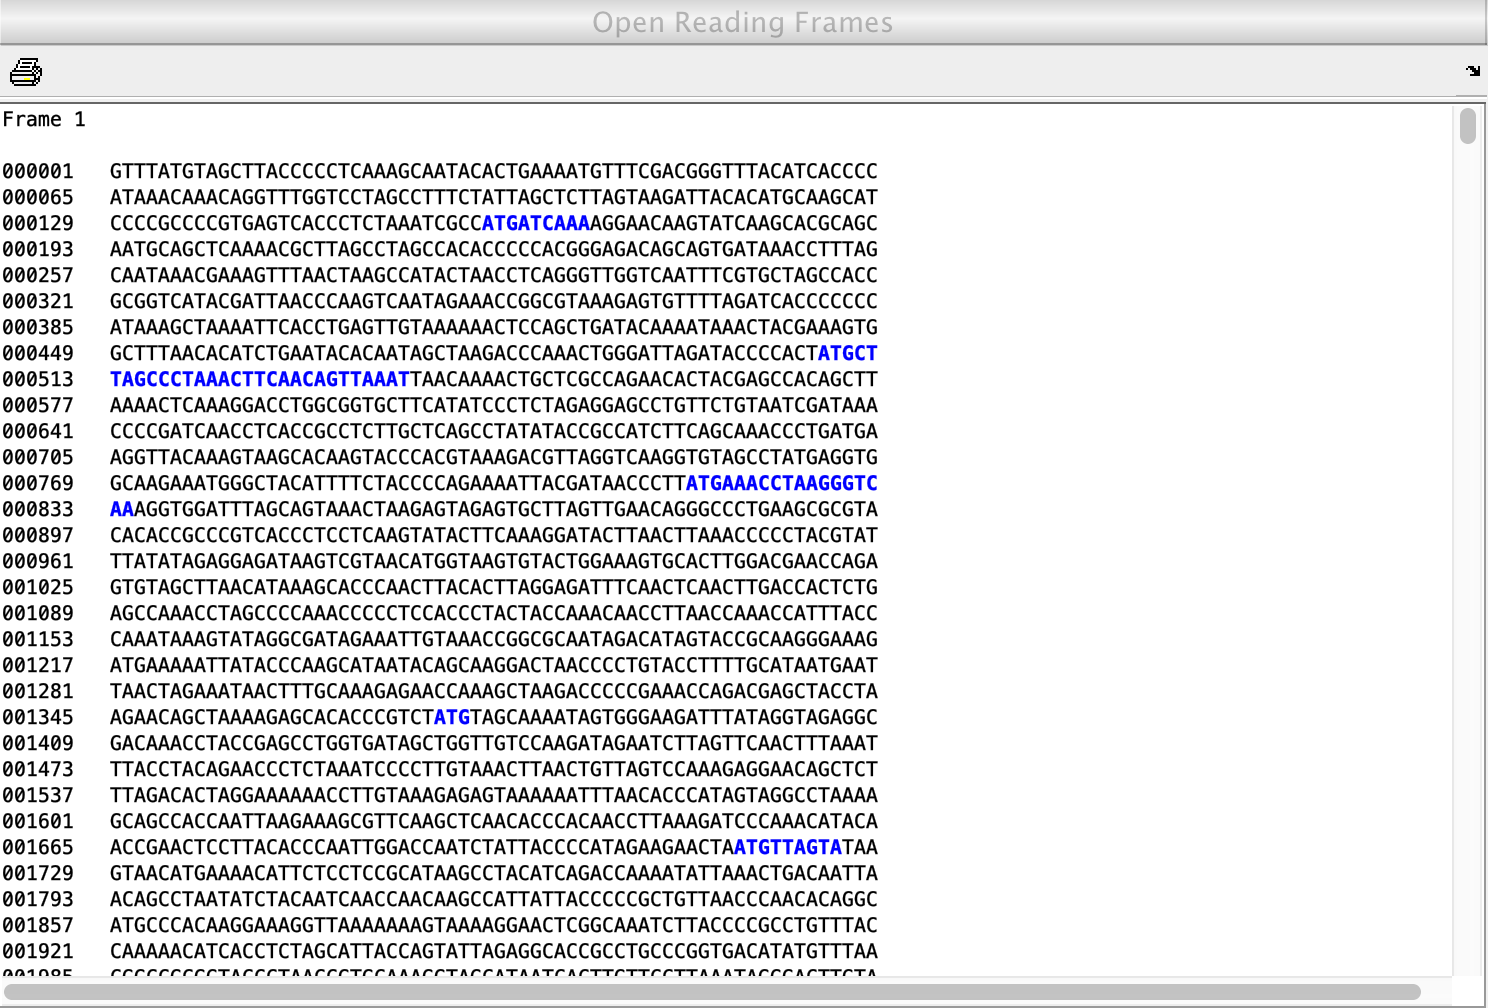

orf = seqshoworfs(chimp,'MINIMUMLENGTH',1, 'geneticcode',2,'frames','all');

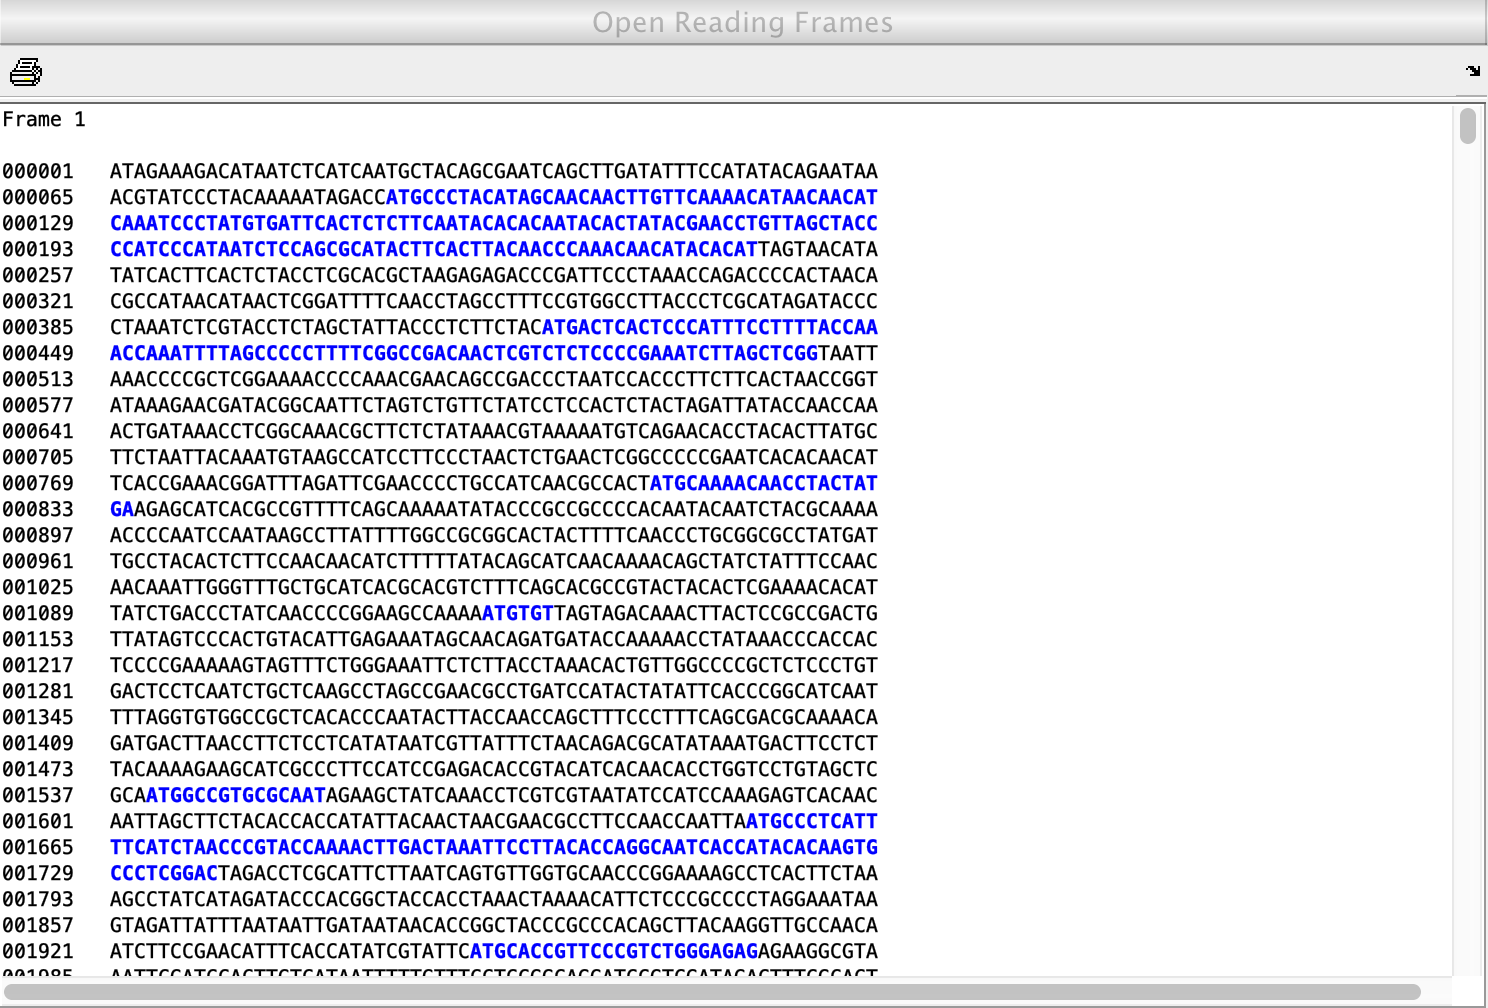

orf1= seqshoworfs(chimp(randperm(length(chimp))),'MINIMUMLENGTH',1,'geneticcode',2,'frames','all');

ORFLength=[];
for i=1:6
   for j=1:length(orf(i).Stop)
    ORFLength=[ORFLength; orf(i).Stop(j)+2 - orf(i).Start(j)];
   end
end
length(ORFLength)

ans = 432

ORFLength1=[];
for i=1:6
   for j=1:length(orf1(i).Stop)
    ORFLength1=[ORFLength1; orf1(i).Stop(j)+2 - orf1(i).Start(j)];
   end
end
length(ORFLength1)

ans = 457

max_threshold=max(ORFLength1)

max_threshold = 245

n_max=length(find(ORFLength>=max_threshold))

n_max = 12

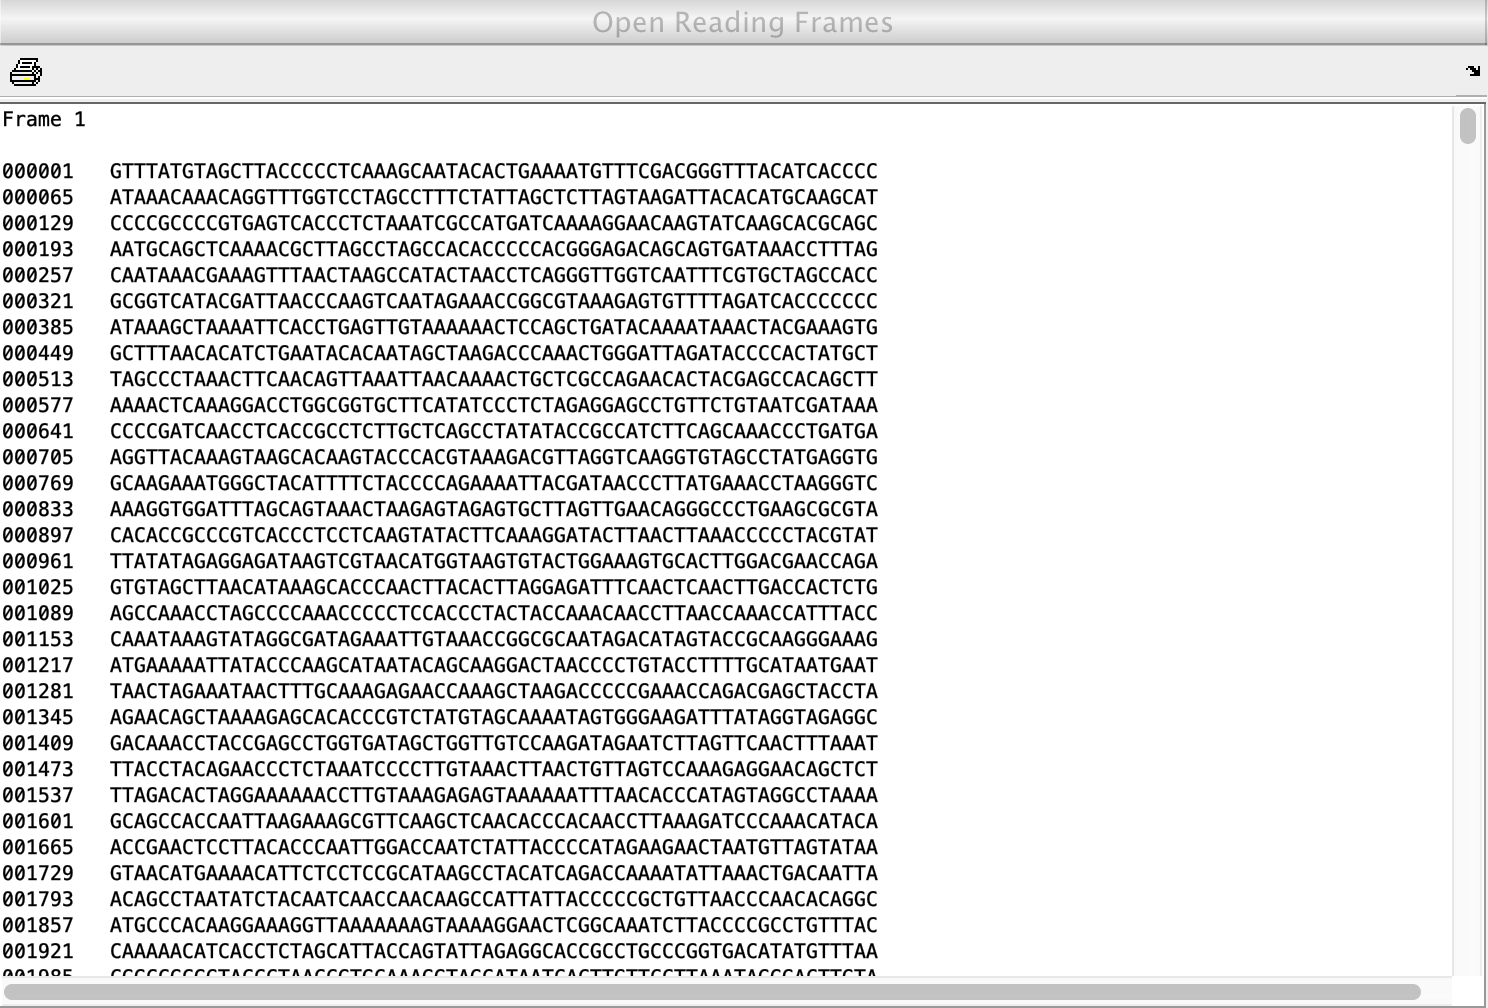

orf_threshold = seqshoworfs(chimp,'MINIMUMLENGTH',max_threshold/3, 'geneticcode',2,'frames','all');

orfNew=[];
for i=1:6
    for j=1:length(orf_threshold(i).Stop)
        orfNew=[orfNew; orf_threshold(i).Stop(j)+2 - orf_threshold(i).Start(j)];
    end
end
length(orfNew)

ans = 12

codons=[];
aminoacid=[];
for i=1:6
    for j= 1:length(orf_threshold(i).Stop)
        proteinSeq = chimp(orf_threshold(i).Start(j):orf_threshold(i).Stop(j)+2);
        codons= [codons; string(proteinSeq)];
        aminoacid = [aminoacid; string(nt2aa(proteinSeq, 'geneticcode',2)),orf_threshold(i).Start(j),orf_threshold(i).Stop(j)+2];
    end
end
length(codons)

ans = 12

length(aminoacid)

ans = 12